clear;clc;close all;

%NEED TO CHECK THAT THE FILTER IS STABLE - ALL POLES ARE IN UNIT CIRCLE

%if user gives complex root, it must have its congujate!!! Z=a+jb & Z*=a-jb
% User input: enter the poles and zeros as vectors
%-----------------------%
opt = 0

opt = 0

if(opt)
    %User enters poles and zeros
    zuser = [0.8,0.3,0.9+0.4i,0.9-0.4i,-1];
    puser = [-1.1,0.1+0.3i,0.1-0.3i];

    zlen = length(zuser)
    plen = length(puser)

    %add poles or zeros at (0,0) so the system will be casual
    if zlen > plen %MA or ARMA
        p = [zeros(1,zlen-plen)]
        z = zuser
        p = [p,puser]
    else %AR or ARMA
        z = [zeros(1,plen-zlen)]
        z = [z,zuser]
        p = puser
    end

else
    %-----------------------%
    %-----------------------%
    %or user enters transfer function b,a
    %MA
    buser = [1,0.3,0.8];
    auser = [1];
    %AR
    %buser = [1,0.2];
    %auser = [1,0.2,0.6];

    blen = length(buser)
    alen = length(auser)

    if blen > alen %MA
        a = [zeros(1,blen-alen)]
        a = [auser,a]
        b = buser
    else %AR
        b = [zeros(1,alen-blen)]
        b = [buser,b]
        a = auser
    end
   
    p = roots(a)
    z = roots(b)

end

blen = 3

alen = 1

a =      0     0


a =      1     0     0


b =     1.0000    0.3000    0.8000


p =      0
     0


z =   -0.1500 + 0.8818i
  -0.1500 - 0.8818i


%b = [1,0.3,0.8]
%a = [1,zeros(1,length(b)-1)]
%-----------------------%


%-----------------------%
% Create a transfer function using poles and zeros
sys_zpk = zpk(z, p, 1,-1,'variable','z^-1')

sys_zpk =
 
  (1 + 0.3z^-1 + 0.8z^-2)
 
Sample time: unspecified
Discrete-time zero/pole/gain model.
Model Properties


% Convert to transfer function form
sys_tf = tf(sys_zpk)

sys_tf =
 
  1 + 0.3 z^-1 + 0.8 z^-2
 
Sample time: unspecified
Discrete-time transfer function.
Model Properties


%-----------------------%

%-----------------------%
%THIS MIGHT BE REDUNDENT AND REMOVED
% Convert the transfer function to symbolic representation
disp('Transfer Function:');

Transfer Function:


%turn this into a function - might remove this because its ugly and not
%working good
syms s;
Den = sys_zpk.P;
Numi = sys_zpk.Z;
sys_1syms = poly2sym(cell2mat(Numi),s)/poly2sym(cell2mat(Den),s);
sys_decimal_no_roots = vpa(sys_1syms, 4)% 4 significant digits, adjust as needed

$$sys\_decimal\_no\_roots = -\infty -\mathrm{i}\,\infty$$


Den = cell2mat(sys_tf.Denominator);
Numi = cell2mat(sys_tf.Numerator);
sys_sym_tf = poly2sym(Numi, s) / poly2sym(Den, s);
sys_decimal_roots = vpa(sys_sym_tf, 4)% 4 significant digits, adjust as needed

$$sys\_decimal\_roots = \frac{s^{2}+0.3\,s+0.8}{s^{2}}$$

%-----------------------%

%-----------------------%
%Plot pole zero response
%[bb,aa] = zp2tf(z,p,1) %this is the same as poly
a = poly(p) %transform roots into poly form

a =      1     0     0


b = poly(z) %transform roots into poly form

b =     1.0000    0.3000    0.8000


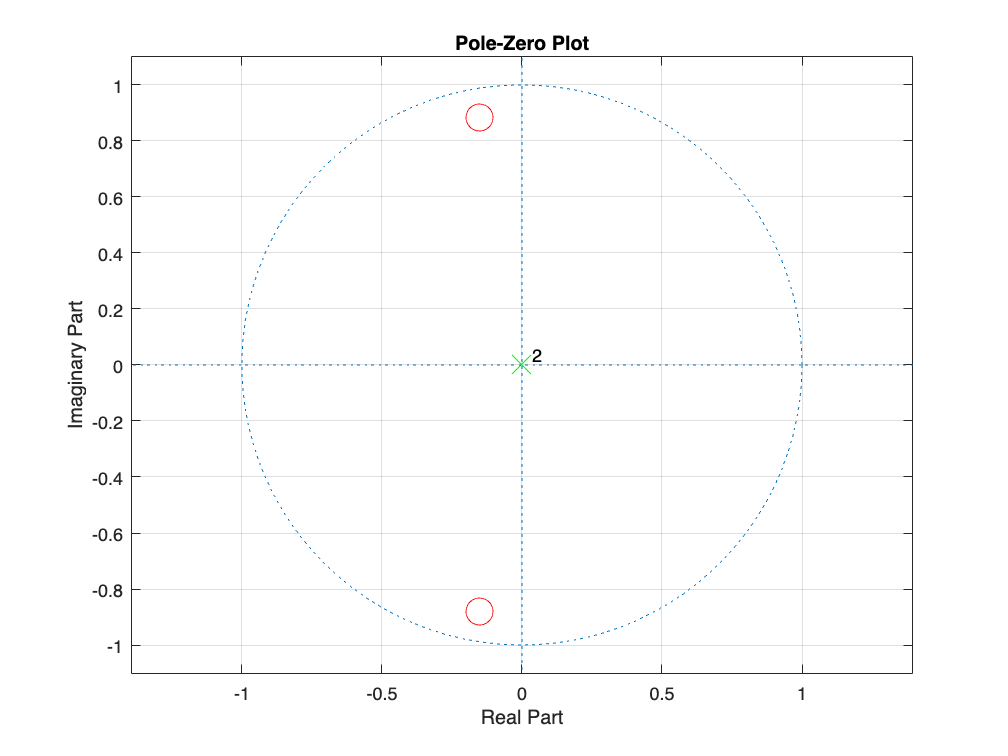

figure; zplane(b,a); grid on; %plot transfer function zeros\poles
h = findobj(gcf, 'Type', 'line');
set(h(2), 'Color', 'green','MarkerSize', 15);  % Zeros in green
set(h(3), 'Color', 'red','MarkerSize', 15);    % Poles in red

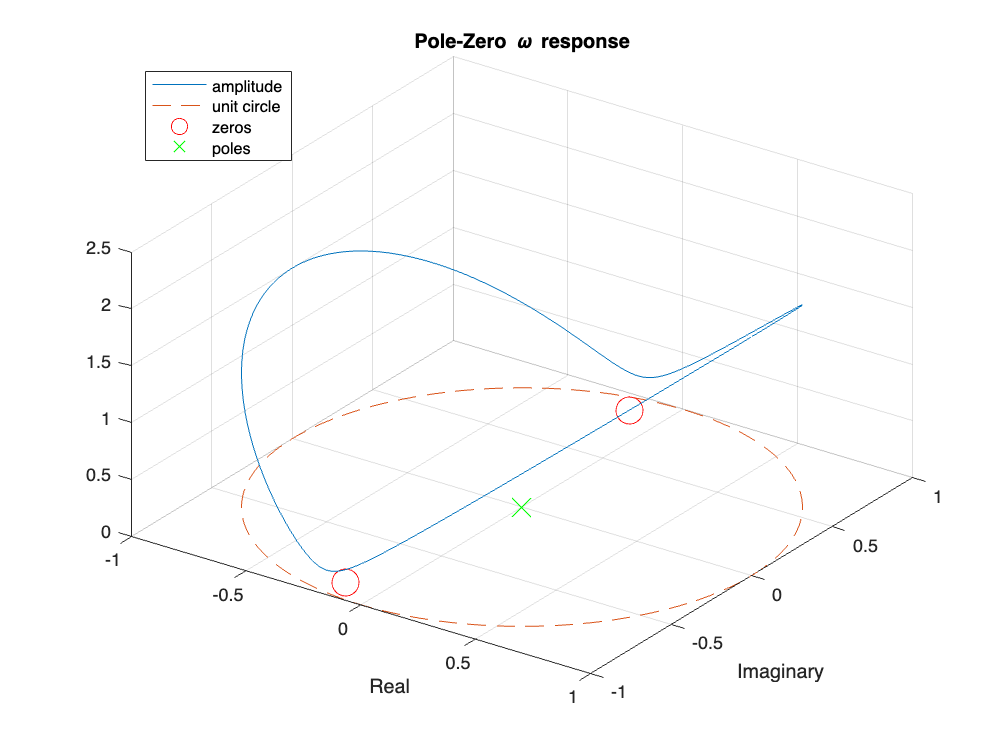


[hw,fw] = zerophase(b,a,1024,"whole");
plot3(cos(fw),sin(fw),hw,'DisplayName','amplitude'); hold on
plot3(cos(fw),sin(fw),zeros(size(fw)),'--','DisplayName','unit circle')
plot3(real(z),imag(z),zeros(size(z)),'o','DisplayName','zeros')
plot3(real(p),imag(p),zeros(size(p)),'x','DisplayName','poles')
hold off; xlabel("Real"); ylabel("Imaginary"); view(35,40); grid on; title("Pole-Zero \omega response")
h = findobj(gcf, 'Type', 'line');
set(h(1), 'Color', 'green','MarkerSize', 15);  % Zeros in green
set(h(2), 'Color', 'red','MarkerSize', 15);    % Poles in red
leg = legend;
leg.Location = 'northwest';

%-----------------------%


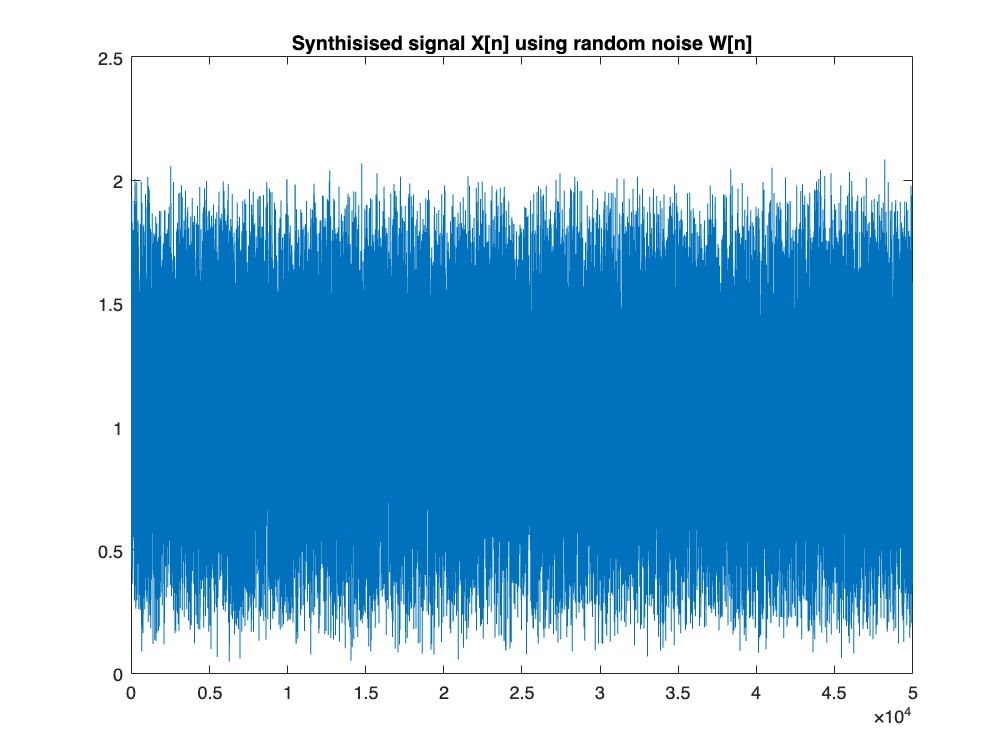

%-----------------------%
sigma0 = 1;
%synthesis x[n] using transfer function and w[n]
Wn = rand(1,10^5);
N = 5*10^4;
xn = filter(b,a,Wn(1:N));
plot(xn,'DisplayName','X[n]'); title("Synthisised signal X[n] using random noise W[n]")


sys_tf

sys_tf =
 
  1 + 0.3 z^-1 + 0.8 z^-2
 
Sample time: unspecified
Discrete-time transfer function.
Model Properties



a = cell2mat(sys_tf.Denominator)

a =      1     0     0


b = cell2mat(sys_tf.Numerator)

b =     1.0000    0.3000    0.8000


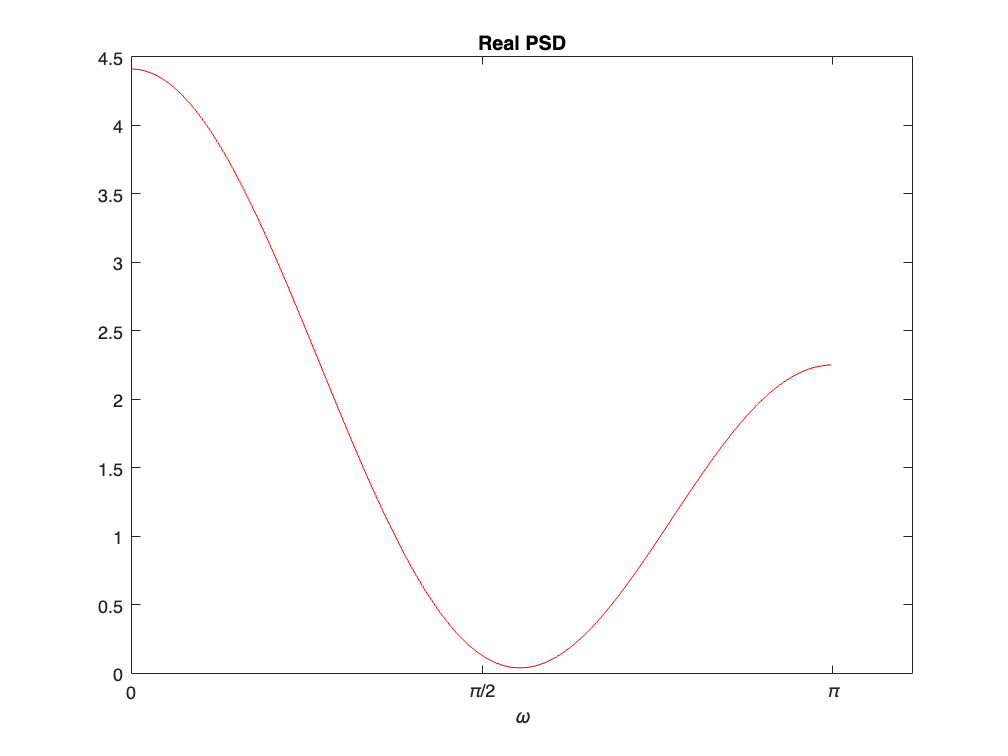


[Hz,omega] = freqz(b,a,512); %plot REAL PSD
real_psd = sigma0*abs(Hz).^2;
log_real_psd = 10*log10(real_psd);
plot(omega,real_psd,'r'); title("Real PSD"); xlabel("\omega"); set(gca,'XTick',0:pi/2:2*pi); set(gca,'XTickLabel',{'0','\pi/2','\pi','1.5\pi','2\pi'}); 

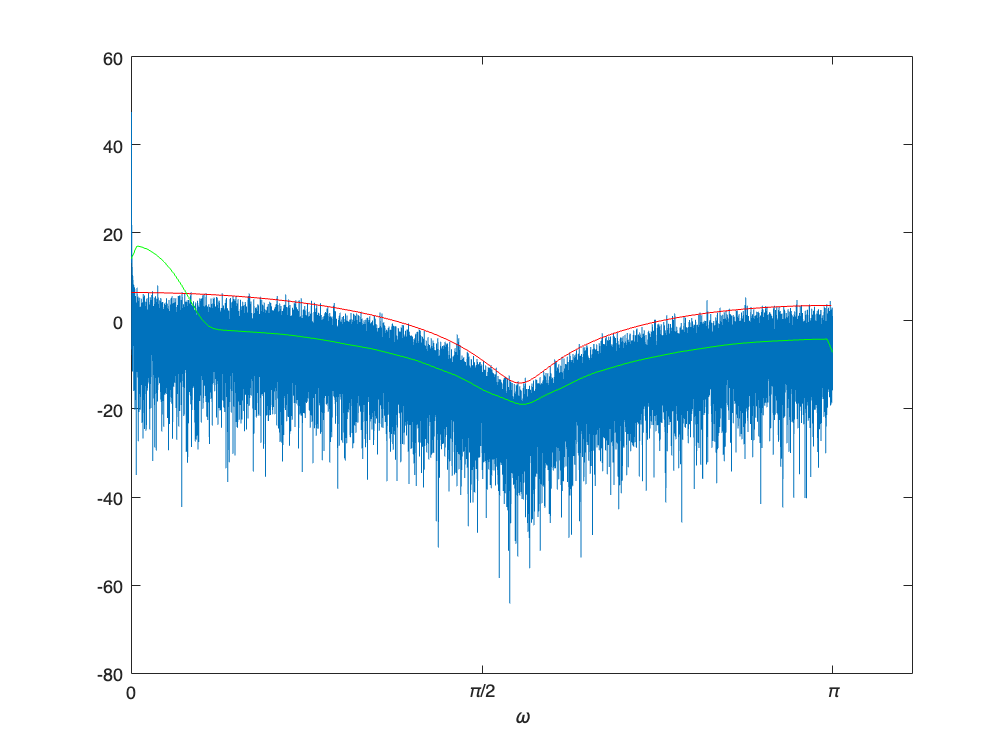

%-----------------------%
%INNA HERE IDK
[psd_period,w] = periodogram(xn);
plot(w,10*log10(2*pi*psd_period)); hold on;
plot(omega,log_real_psd,'r');  xlabel("\omega"); set(gca,'XTick',0:pi/2:2*pi); set(gca,'XTickLabel',{'0','\pi/2','\pi','1.5\pi','2\pi'}); 
hold on;
%-----------------------%
%periodogram(xn,[]); hold on
L = 32;%window length
D = L/2; %overlap amount
K = (N-L)/D +1; %num of sub groups
windowtype = hamming(L); %bartlett(L)
[psd_welch,ww] = pwelch(xn,windowtype,D); 
plot(ww,10*log10(2*pi*psd_welch),'g')

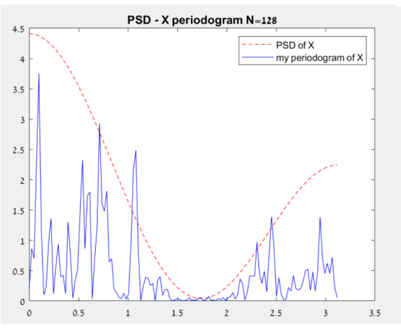

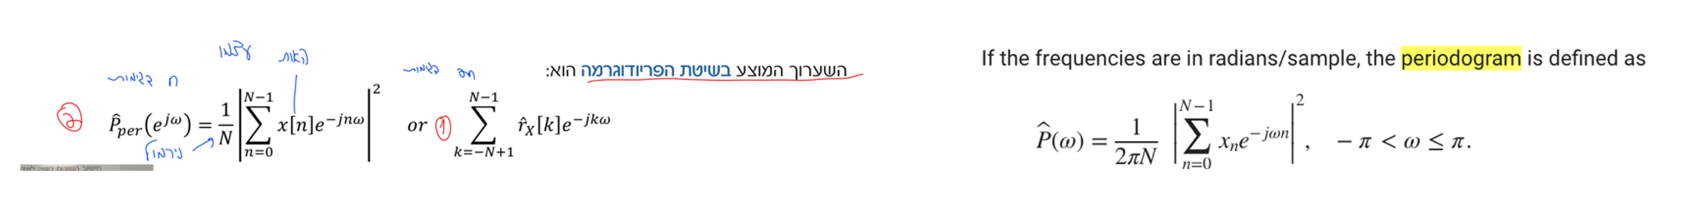

PARAMETRIC FOR AR ONLY:

Calculate rx[k] with biased estimate

calculate